**                                                                Applied Linear Control - Midterm Project**

**                                                                                        Rohit Murali**

**Section 1**: Construct an excitation for system identification. Compute and plot the properly scaled power spectrum for the excitation. Demonstrate that your excitation signal does not saturate the DAC by plotting your entire excitation in the time domain.

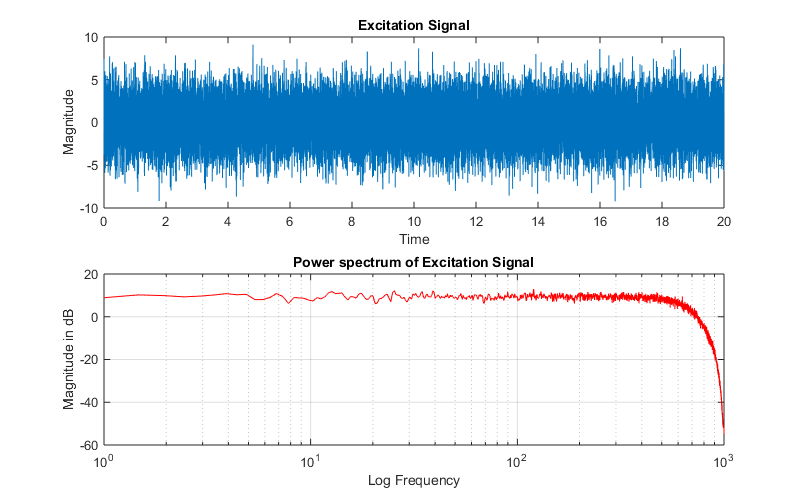

N = 40000;
u = 3*randn(1,N);
zero_input = 3*zeros(1,N);
fs = 2000;
Ts = 1/fs;
[num, den] = butter(2, 600/(fs/2));
t = Ts*[0:N-1];
excitation = filter(num, den, u);
figure('Position',[100, 100, 800, 500]);
subplot(2,1,1);
plot(t, excitation)
title('Excitation Signal');
xlabel('Time');
ylabel('Magnitude');
Fbin = fs/N;
fr = Fbin*[0:N-1];
subplot(2,1,2);
nfft = 2^12;
wndo = nfft;
ovlp = nfft/2;
[Puu, FR] = cpsd(excitation,excitation,wndo,ovlp,nfft,fs);
semilogx(FR, 10*log10(abs(Puu)*(fs/2)), 'r')
title('Power spectrum of Excitation Signal');
xlabel('Log Frequency');
ylabel('Magnitude in dB');
xlim([1, fs/2]);
grid on;

**Section 2**: Apply the excitation to the dynamic system (s20_plant) to obtain the noisy response signals. Estimate and display the SNR (dB) for each of the two paths. HINT: Your System ID results will be much better if you attempt to maximize the SNR; however, you are not allowed to saturate (i.e. clip) either the excitations or the responses!

y = s20_plant(excitation)

*** Warning:  Response saturated 2/40000 samples (0.005%)


y =     0.1524    0.8159    1.2304    1.1915    1.2960    1.2059    1.1128    0.7162    0.3915    0.7290    1.0085    1.0389    0.5472   -0.0840   -0.0166    0.4805    0.7466    0.7448    0.3447   -0.3451   -0.4315    0.2723    0.4842   -0.1649   -0.7039   -0.9170   -0.9443   -0.9248   -0.7189   -0.5545   -1.0977   -1.4959   -1.2083   -1.2018   -1.4682   -1.4504   -1.1293   -0.8862   -0.5283    0.0275    0.3402    0.2324   -0.3135   -0.2109    0.6999    1.2396    1.2048    0.5746    0.1724    0.4742
    0.4608    1.8317    2.9610    2.4497    0.6167   -0.6814    0.2400    2.2819    3.0671    1.8070    0.1249   -0.4986    0.3318    2.2996    2.8340    1.1260   -1.0400   -1.1810    0.7259    1.7747    0.9303   -0.2014   -0.7173   -1.1116   -1.0988   -0.0879    0.0421   -1.2869   -2.4058   -2.4111   -1.5200   -1.1140   -1.5325   -2.0987   -2.5779   -2.1263   -0.1894    0.6906   -0.7305   -2.1284   -1.3270    0.6261    1.5234    0.8016   -0.1950   -0.0769    0.4275    0.1810    0.1143    1

y_zero_response = s20_plant(zero_input);
zero_response1 = y_zero_response(1,:);
zero_response2 = y_zero_response(2,:);
response1 = y(1,:);
response2 = y(2,:);
sigma_y1 = std(response1);
sigma_y2 = std(response2);
sigma_n1 = std(zero_response1);
sigma_n2 = std(zero_response2);
SNR_path1 = 10*log10((sigma_y1^2 - sigma_n1^2)/sigma_n1^2)

SNR_path1 = 22.0674

SNR_path2 = 10*log10((sigma_y2^2 - sigma_n2^2)/sigma_n2^2)

SNR_path2 = 22.3407

**Section 3**: Compute and plot the properly scaled power spectrum for the responses. On these same plots, compute and plot the properly scaled power spectrum for the noise signals. Demonstrate that the measured sensor responses do not saturate the ADC’s by plotting the responses in the time domain. The spectrum of y1 and n1 must be in one axes, and the spectrum of y2 and n2 must be in a second axes. The time series plot of y1 and n1 must be in one axes, and the time series plot of y2 and n2 must be in a second axes. You must have four separate axes in a 2x2 grid on a single figure.

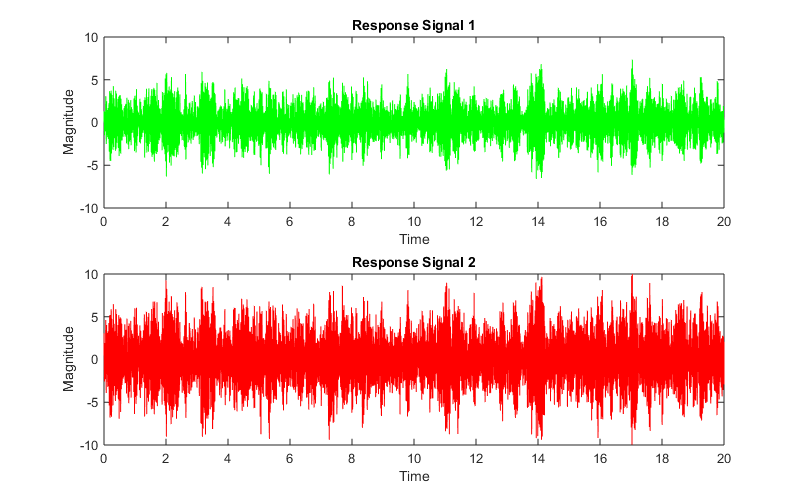

figure('Position',[100, 100, 800, 500]);
subplot(2,1,1)
plot(t, response1, 'g');
title('Response Signal 1');
xlabel('Time');
ylabel('Magnitude');
subplot(2,1,2)
plot(t, response2, 'r');
title('Response Signal 2');
xlabel('Time');
ylabel('Magnitude');

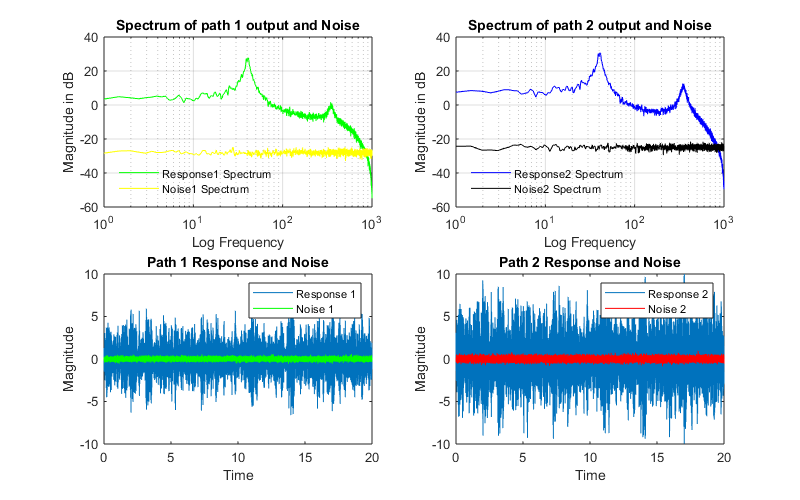

figure('Position',[100, 100, 800, 500]);
subplot(2,2,1);
noise1 = 0.1392*rand(1,N);
[Py1y1, FR] = cpsd(response1,response1,wndo,ovlp,nfft,fs);
semilogx(FR, 10*log10(abs(Py1y1)*(fs/2)), 'g')
hold on;
[Pn1n1, FR] = cpsd(noise1,noise1,wndo,ovlp,nfft,fs);
semilogx(FR, 10*log10(abs(Pn1n1)*(fs/2)), 'y')
title('Spectrum of path 1 output and Noise');
xlabel('Log Frequency');
ylabel('Magnitude in dB');
xlim([1,fs/2]);
grid on;
legend('Response1 Spectrum', 'Noise1 Spectrum', 'Location', 'SouthWest');
legend('boxoff');

subplot(2,2,2);
noise2 = 0.1990*rand(1,N);
[Py2y2, FR] = cpsd(response2,response2,wndo,ovlp,nfft,fs);
semilogx(FR, 10*log10(abs(Py2y2)*(fs/2)), 'b')
hold on;
[Pn2n2, FR] = cpsd(noise2,noise2,wndo,ovlp,nfft,fs);
semilogx(FR, 10*log10(abs(Pn2n2)*(fs/2)), 'k')
title('Spectrum of path 2 output and Noise');
xlabel('Log Frequency');
ylabel('Magnitude in dB');
xlim([1, fs/2]);
grid on;
legend('Response2 Spectrum', 'Noise2 Spectrum', 'Location', 'SouthWest');
legend('boxoff');

subplot(2,2,3);
plot(t, response1, t, zero_response1, 'g');
title('Path 1 Response and Noise');
xlabel('Time');
ylabel('Magnitude');
legend('Response 1', 'Noise 1');

subplot(2,2,4);
plot(t, response2, t, zero_response2, 'r');
title('Path 2 Response and Noise');
xlabel('Time');
ylabel('Magnitude');
legend('Response 2', 'Noise 2');

**Section 4**: Apply an appropriate frequency domain estimation technique from the course to estimate frequency response functions for each open-loop path. Estimate the coherence associated with each path. This data will be plotted in a later section.

[H1,ft] = tfestimate(excitation,response1,wndo,ovlp,nfft,fs);
[H1y2,ft] = tfestimate(excitation,response2,wndo,ovlp,nfft,fs);
COH1 = mscohere(excitation,response1,wndo,ovlp,nfft,fs);
COH2 = mscohere(excitation,response2,wndo,ovlp,nfft,fs);

**Section 5**: Use the invfreqz function to estimate discrete time transfer function models for each of the two paths in the open-loop plant. You must choose exactly the same number of poles for each path. Store your estimated numerator and denominator polynomials in a Matlab cell array with appropriate dimensions to match the dynamic system dimensions. Convert the numerator and denominator cell arrays into a discrete time transfer function LTI object. Convert this LTI object into a minimum realization using the minreal function.

[B1, A1] = invfreqz(H1, 2*pi*ft/fs, 5, 5, Py1y1, 10);
[B2, A2] = invfreqz(H1y2, 2*pi*ft/fs, 5, 5, Py2y2, 10);
test1 = freqz(B1, A1, FR, fs);
test2 = freqz(B2, A2, FR, fs);
tf1 = tf(B1, A1, Ts);
tf2 = tf(B2, A2, Ts);
Hsys = [tf1; tf2];
minimum_real = minreal(Hsys);

**Section 6**: Convert the minimum realization transfer function LTI object from Section 5 into a discrete-time state-space LTI object. Input the discrete-time state-space model to the balreal function in Matlab to generate a balanced realization and extract the Hankel singular values for the estimated model. Plot the Hankel singular values in a bar chart to determine an appropriate cutoff threshold for pruning non-contributing modes from the resulting LTI state-space object. Use the modred function in Matlab to generate a reduced order LTI discrete time state-space model. Read the Matlab help for the minreal, balreal, and modred functions to learn more about how these functions work.

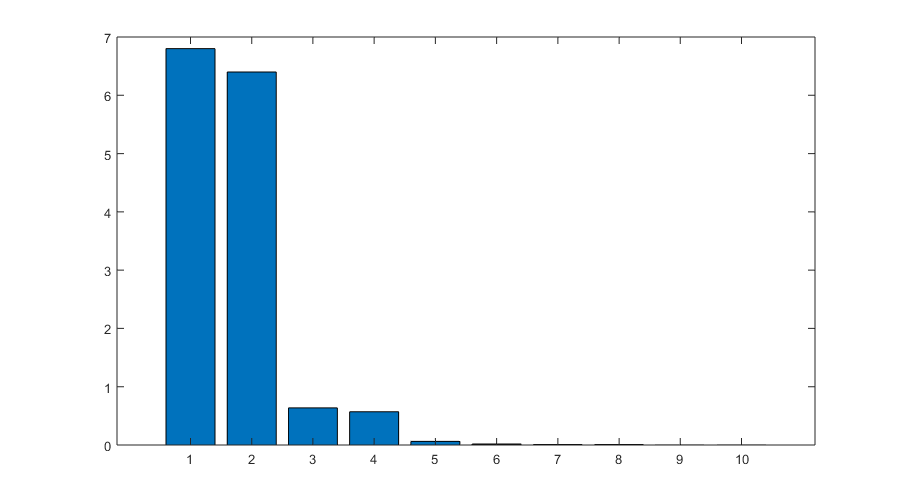

Hss = ss(minimum_real);
[min_real, g] = balreal(Hss);
figure('Position',[100, 100, 900, 500]);
bar(g)

figure;
reduced_ss = modred(min_real, 6:10, 'MatchDC');

**Section 7**: Compute the z-domain eigenvalues (poles) of the LTI object result from Section 6. Compute the natural frequencies with units of Hz, and the damping ratios associated with every eigenvalue.

[a,b,c,d,Ts] = ssdata(reduced_ss);
[Bss1, Ass1] = ss2tf(a,b,c(1,:),d(1,1));
tfss1 = tf(Bss1, Ass1, Ts);
[Bss2, Ass2] = ss2tf(a,b,c(2,:),d(2,1));
tfss2 = tf(Bss2, Ass2, Ts);
poles_section6 = eig(a)

poles_section6 =    0.9868 + 0.1270i
   0.9868 - 0.1270i
   0.4256 + 0.8403i
   0.4256 - 0.8403i
   0.2056 + 0.0000i


damp(reduced_ss)

                                                                                    
         Pole             Magnitude     Damping       Frequency      Time Constant  
                                                    (rad/seconds)      (seconds)    
                                                                                    
  9.87e-01 + 1.27e-01i     9.95e-01     3.93e-02       2.56e+02         9.93e-02    
  9.87e-01 - 1.27e-01i     9.95e-01     3.93e-02       2.56e+02         9.93e-02    
  4.26e-01 + 8.40e-01i     9.42e-01     5.42e-02       2.21e+03         8.36e-03    
  4.26e-01 - 8.40e-01i     9.42e-01     5.42e-02       2.21e+03         8.36e-03    
  2.06e-01                 2.06e-01     1.00e+00       3.16e+03         3.16e-04    


**Section 8**: Compute the eigenvalues (poles) for both of the discrete time open-loop transfer function models you estimated in Section 5. Use the zgrid function in Matlab to generate a z-domain grid, and then plot each set of poles on this plot using clearly labeled markers for each of the estimated path models. Do NOT plot the zeros! There should be three sets of poles on the plot: one for the y1 path (Section 5), one for the y2 path (Section 5), and one for the final discrete-time state-space model (Section 6). All markers should be the same for the poles associated with the same path. You must use the axis equal command to scale the plot correctly.

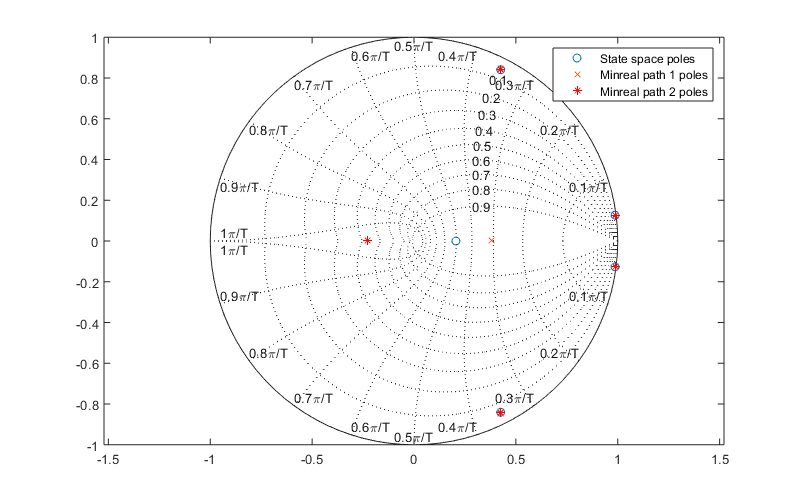

section5_ss1 = ss(tf1);
section5_ss2 = ss(tf2);
[a1, b1, c1, d1, Ts] = ssdata(section5_ss1);
[a2, b2, c2, d2, Ts] = ssdata(section5_ss2);
poles_section5_path1 = eig(a1);
poles_section5_path2 = eig(a2);
real_section6 = real(poles_section6);
imag_section6 = imag(poles_section6);

real_section5_path1 = real(poles_section5_path1);
imag_section5_path1 = imag(poles_section5_path1);

real_section5_path2 = real(poles_section5_path2);
imag_section5_path2 = imag(poles_section5_path2);
figure('Position',[100, 100, 800, 500]);
zgrid(2*pi*Ts, 'new')
hold on;
h = plot(real_section6, imag_section6, 'o', real_section5_path1, imag_section5_path1, 'x', real_section5_path2, imag_section5_path2, 'r*');
zgrid
axis equal;
legend(h,'State space poles', 'Minreal path 1 poles', 'Minreal path 2 poles');

**Section 9**: Compute the frequency response of the final discrete-time state-space LTI object result from Section 5 using the freqresp function. Compute the frequency response of the final discrete-time state-space LTI object result from Section 6 using the freqresp function.

save('Discrete_SS', 'a', 'b', 'c', 'd');
section5_resp1 = squeeze(freqresp(minimum_real(1,1),2*pi*fr));
section6_resp1 = squeeze(freqresp(tfss1,2*pi*fr));
section5_resp2 = squeeze(freqresp(minimum_real(2,1),2*pi*fr));
section6_resp2 = squeeze(freqresp(tfss2,2*pi*fr));

**Section 10**: Compare the results of your estimation in the frequency domain by generating dB magnitude vs. log frequency and phase (degrees) vs. log frequency plots (a.k.a. Bode diagrams) for each path. You must directly plot the estimated frequency response from Section 4 on top of the frequency response from the transfer function results in Section 5 and the frequency response from the state-space results in Section 6. There will be two figures and on each figure there will be three axes displayed in a 3x1 grid: one for coherence, one for phase, and one for magnitude. All three frequency response curves must be properly labeled and displayed for visual inspection.

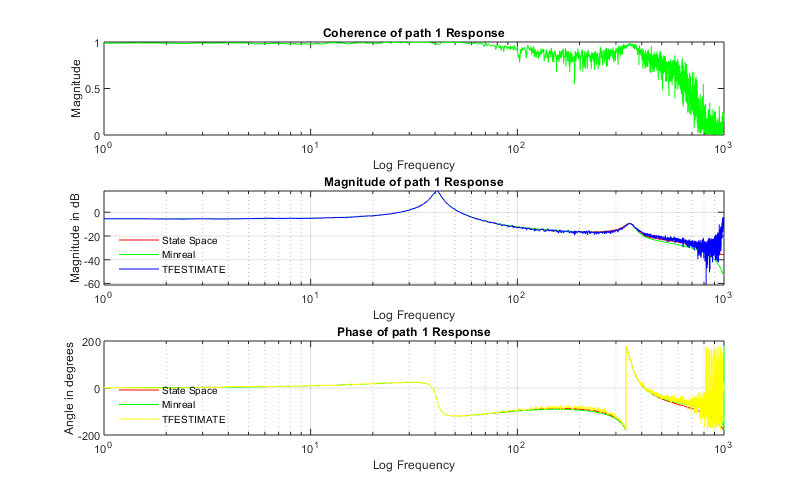

figure('Position',[100, 100, 800, 500]);
subplot(3,1,1);
semilogx(FR, COH1, 'g')
xlim([1, fs/2]);
title('Coherence of path 1 Response');
xlabel('Log Frequency');
ylabel('Magnitude');

subplot(3,1,2);
semilogx(fr,20*log10(abs(section6_resp1)), 'r')
hold on;
semilogx(fr,20*log10(abs(section5_resp1)), 'g')
hold on;
semilogx(FR, 20*log10(abs(H1)), 'b');
xlim([1, fs/2]);
title('Magnitude of path 1 Response');
xlabel('Log Frequency');
ylabel('Magnitude in dB');
legend('State Space', 'Minreal', 'TFESTIMATE','Location', 'Southwest');
legend('boxoff');
grid on;

subplot(3,1,3);
semilogx(fr,(180/pi)*angle(section6_resp1), 'r')
hold on;
semilogx(fr,(180/pi)*angle(section5_resp1), 'g') 
hold on;
semilogx(ft,(180/pi)*angle(H1), 'y');
xlim([1, fs/2]);
title('Phase of path 1 Response');
xlabel('Log Frequency');
ylabel('Angle in degrees');
legend('State Space', 'Minreal', 'TFESTIMATE', 'Location', 'Southwest');
legend('boxoff');
grid on;

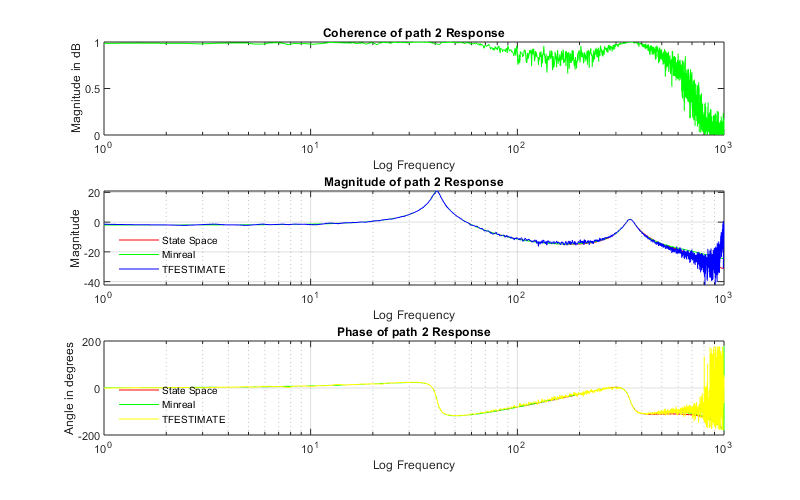

figure('Position',[100, 100, 800, 500]);
subplot(3,1,1);
semilogx(FR, COH2, 'g')
xlim([1, fs/2]);
title('Coherence of path 2 Response');
xlabel('Log Frequency');
ylabel('Magnitude in dB');

subplot(3,1,2);
semilogx(fr,20*log10(abs(section6_resp2)), 'r')
hold on;
semilogx(fr,20*log10(abs(section5_resp2)), 'g')
hold on;
semilogx(ft, 20*log10(abs(H1y2)), 'b');
xlim([1, fs/2]);
title('Magnitude of path 2 Response');
xlabel('Log Frequency');
ylabel('Magnitude');
legend('State Space', 'Minreal', 'TFESTIMATE','Location', 'Southwest');
legend('boxoff');
grid on;

subplot(3,1,3);
semilogx(fr,(180/pi)*angle(section6_resp2), 'r')
hold on;
semilogx(fr,(180/pi)*angle(section5_resp2), 'g')
hold on;
semilogx(ft,(180/pi)*angle(H1y2), 'y');
xlim([1, fs/2]);
title('Phase of path 2 Response');
xlabel('Log Frequency');
ylabel('Angle in degrees');
legend('State Space', 'Minreal', 'TFESTIMATE','Location', 'Southwest');
legend('boxoff');
grid on;